syms s;

num = 100;
den = sym2poly(s+30);

G = tf(num, den);
T = feedback(G,1);

pole(T)

ans = -130

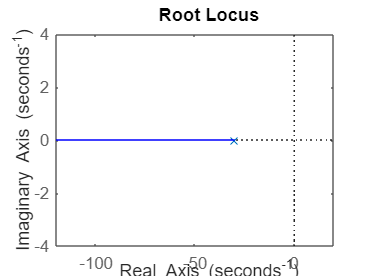

rlocus(G)

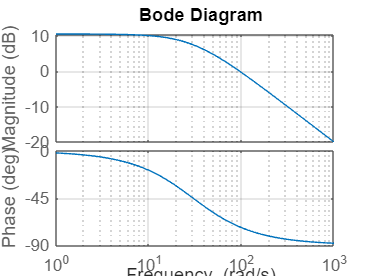

bode(G), grid

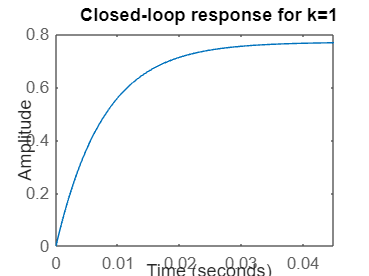

step(T), title('Closed-loop response for k=1')


[Gm,Pm] = margin(2*G);
GmdB = 20*log10(Gm)   % gain margin in dB

GmdB = Inf

Pm  % phase margin in degrees

Pm = 98.6269

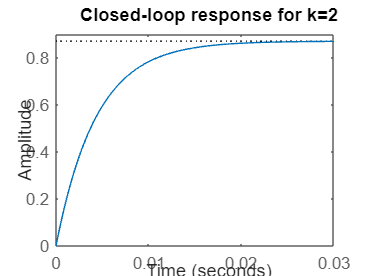


step(feedback(2*G,1)), title('Closed-loop response for k=2')